# Comparing Controller with all Patients from Jost

clear all;
clc; 
close all; 

DataSheet1 = readmatrix("Data Sheet 1.csv");
DataSheet2 = readmatrix("Data Sheet 2.csv");

total_patients = DataSheet2(end, 1);

ans = 216

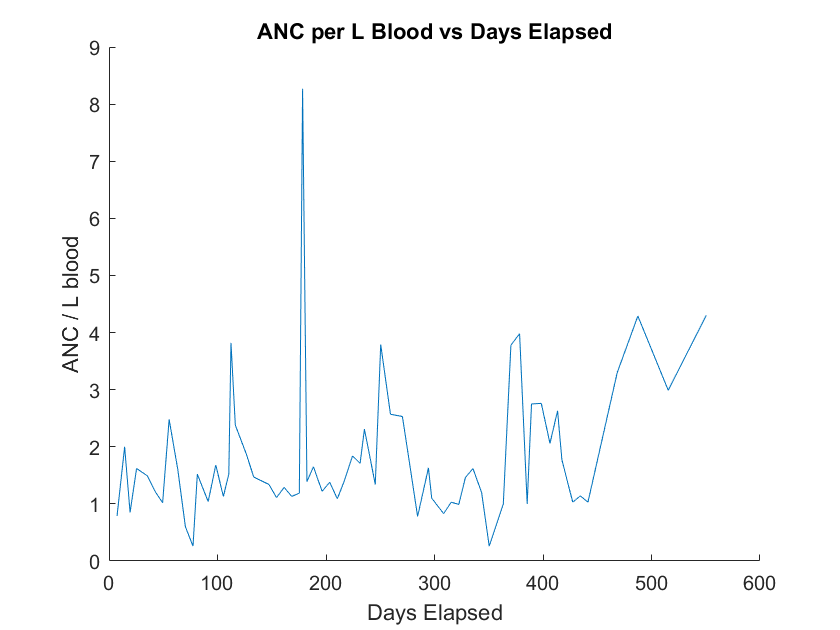

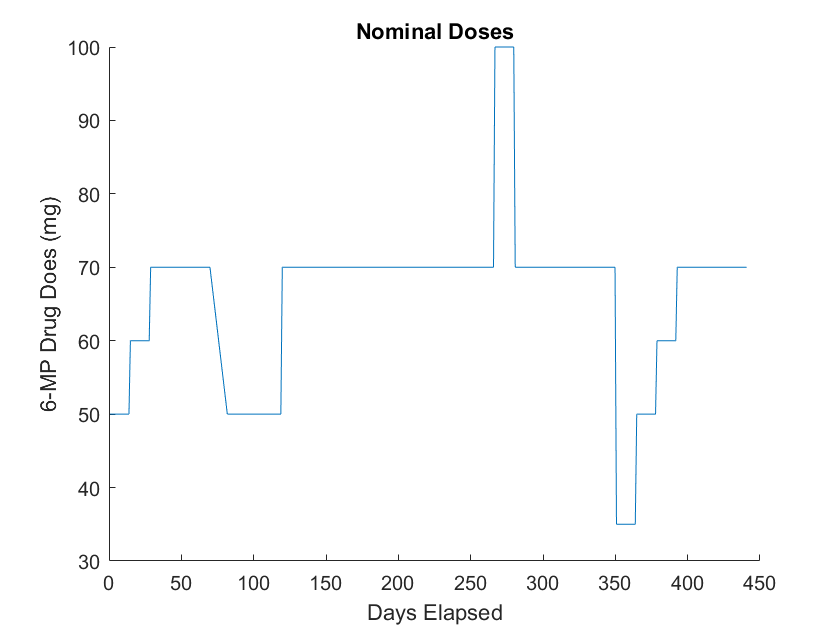

Start Time | End Time | Length


    0.7917    6.7917    7.0000
    7.7917   13.7920    7.0000
   14.7920   18.7920    5.0000
   19.7920   24.7920    6.0000
   25.7920   34.7920   10.0000
   35.7920   41.7920    7.0000
   42.7920   48.7920    7.0000
   49.7920   54.7920    6.0000
   55.7920   62.7920    8.0000
   63.7920   69.7920    7.0000
   81.7920   90.7920   10.0000
   91.7920   97.7920    7.0000
   98.7920  104.7900    7.0000
  105.7900  109.7900    5.0000
  110.7900  111.7900    2.0000
  112.7900  115.7900    4.0000
  116.7900  125.7900   10.0000
  126.7900  132.7900    7.0000
  133.7900  146.7900   14.0000
  147.7900  153.7900    7.0000
  154.7900  160.7900    7.0000
  161.7900  167.7900    7.0000
  168.7900  174.7900    7.0000
  175.7900  177.7900    3.0000
  178.7900  181.7900    4.0000
  182.7900  187.7900    6.0000
  188.7900  195.7900    8.0000
  196.7900  202.7900    7.0000
  203.7900  209.7900    7.0000
  210.7900  215.7900    6.0000
  216.7900  223.7900    8.0000
  224.7900  230.7900    7.0000
  231.79

Note that the length is +1 more than it seems because the dose carries onto the next day.


% population parameters (from Jost et al.)
population_params = [2.06; 0.146; 0.103; 0.866];

for patientID = 1:total_patients
    
    p_actual = DataSheet1(patientID, 2:5)';
    p_guess = population_params;
    
    patient_data    = [];
    patient_doses   = [];
    patient_evid    = [];
    patient_cycles  = [];
    simulation_time = [];
    cycle_start_time = 10000; % can be arbitrary because will be overwritten
    last_measurement = true;
    
    for k=1:length(DataSheet2)
        patient_id  = DataSheet2(k,1);
        time        = DataSheet2(k,2);
        measurement = DataSheet2(k,3);
        dose        = DataSheet2(k,5);
        evid        = DataSheet2(k,7);
        
        if patient_id - 100 == patientID
            bsa = DataSheet2(k,11);
            if measurement ~= 0
                patient_data = [patient_data; time measurement];
                if last_measurement == false
                    patient_cycles = [...
                        patient_cycles;...
                        cycle_start_time ...
                        prev_time ...
                        round(abs(prev_time - cycle_start_time) + 1)];
                    last_measurement = true;
                end
            else
                if last_measurement == true
                    cycle_start_time = time;
                    last_measurement = false;
                end
            end
            if evid
                patient_doses = [patient_doses; time dose];
            end
            patient_evid = [patient_evid; time evid];
            simulation_time = [simulation_time; time];
        end
        
        prev_time = time;
    end
    figure()
    hold on
    xlabel('Days Elapsed')
    ylabel('ANC / L blood')
    title("ANC per L Blood vs Days Elapsed")
    plot(patient_data(:,1), patient_data(:,2))
    hold off
    
    figure()
    hold on
    xlabel('Days Elapsed')
    ylabel('6-MP Drug Does (mg)')
    title("Nominal Doses")
    plot(patient_doses(:,1), patient_doses(:,2))
    hold off
    
    disp("Start Time | End Time | Length")
    disp(patient_cycles);
    disp("Note that the length is +1 more than it seems because the dose carries onto the next day.")

    theta = [ ...    
        31.2; ...
        12.72; ...
        0.019; ...
        9.9216; ...
        0.219*(bsa^1.16); ...
        p_actual(1); ...
        p_actual(2); ...
        p_actual(3); ...
        p_actual(4); ...
        2.3765; ...
    ];
    
    % initial values (from Jost et al.)
    x0 = [0;...
        0;...
        0;...
        theta(6)*theta(10)/theta(7);...
        theta(6)*theta(10)/theta(7);...
        theta(6)*theta(10)/theta(7);...
        theta(6)*theta(10)/theta(7);...
        theta(6)];
    
    N = 10; % number of cycles
    N_cycledays = 20; % for Steve we use 21 days
    N_drugdays = 14; % for Steve we use 14 days
    
    % Dimension
    n = 8; % dimension of state vector x 
    m = 1; % dimension of observation vector y
    
    step_size = 0.05;
    num_tpts = N_cycledays/step_size + 1;
    tspan = linspace(0, N_cycledays, num_tpts);
    
    t_oncycle = N_drugdays/step_size;
    t_offcycle = (N_cycledays-N_drugdays)/step_size;
    t_fullcycle = t_oncycle + t_offcycle + 1;
    
    lower = 1; upper = 2;
    var_w = 0.025;
    
    % constraints for dosing plan
    lb_drug = 0.01;
    ub_drug = 50*bsa*2; % note: this is twice the optimal dosing quantity
end